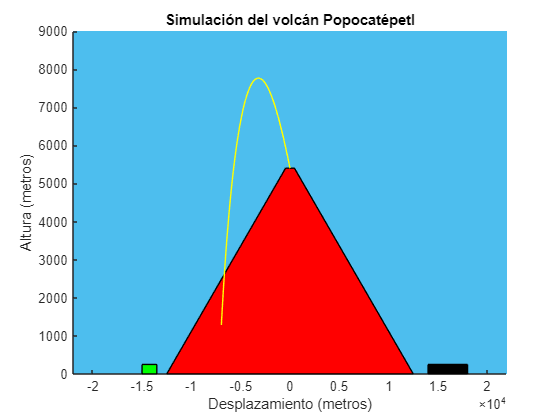

%Entregable dos, proyecto de volcán popocatepetl
clear; 
clc;
close all;

%Distancias reales escenario
altura = 5400; %m
base_mayor = 25000; %m
base_menor = 900; %m
distancia_centro_inicio_ecatzingo= 14000; %m
distancia_centro_fin_ecatzingo= 18000; %m
distancia_centro_inicio_amecameca= -13500; %m
distancia_centro_fin_amecameca= -15000; %m

%Gráfica de las distancias
hold on;
vertices_trapecio_x = [-base_mayor/2, -base_menor/2, base_menor/2,base_mayor/2];
vertices_trapecio_y = [0,altura,altura,0];
axis([-22000,22000,0,9000])
plot(vertices_trapecio_x, vertices_trapecio_y);
vertices_ecatzingo_x = [distancia_centro_inicio_ecatzingo,distancia_centro_inicio_ecatzingo,distancia_centro_fin_ecatzingo,distancia_centro_fin_ecatzingo];
vertices_ecatzingo_y = [0,250,250,0];
plot(vertices_ecatzingo_x,vertices_ecatzingo_y)
vertices_amecameca_x= [distancia_centro_inicio_amecameca,distancia_centro_inicio_amecameca,distancia_centro_fin_amecameca,distancia_centro_fin_amecameca];
vertices_amecameca_y= [0,250,250,0];
plot(vertices_amecameca_x,vertices_amecameca_y)
set(gca, 'Color','#4DBEEE');
solido_volcan=fill(vertices_trapecio_x, vertices_trapecio_y, 'r');
solido_ecatzingo=fill(vertices_ecatzingo_x,vertices_ecatzingo_y,'k');
solido_amecameca=fill(vertices_amecameca_x,vertices_amecameca_y,'g');
title("Simulación del volcán Popocatépetl");
xlabel("Desplazamiento (metros)");
ylabel("Altura (metros)");


%Valores fijos
p = 1.225; %kg/m3
g = 9.81; %m/s2
cd=0.47;
h=0.1;  
tiempo_cd=zeros();
v0_x_cd=zeros();
v0_y_cd=zeros();
posicion_x_cd=zeros();
posicion_y_cd=zeros();
velocidad_total_cd=zeros();
aceleracion_y_cd=zeros();
aceleracion_x_cd=zeros();
alcances_lanzamientos=zeros();
%Método de Euler y valores aleatorias
for i=1:3
    v0_y=randi([100,300]); %m/s, hay dos rangos posibles: de 2.5m/s a 200m/s y de 200m/s a 400m/s
    densidad=randi([2800,2900]); %kg/m3
    radio=0.32+rand*(3-0.32); %m
    volumen_roca=4/3*(pi*radio^3); %m3
    masa=volumen_roca*densidad; %kg
    angulo_tiro=randi([45,135]); %°
    v0_total=v0_y/sind(angulo_tiro); %m/s
    v0_x=cosd(angulo_tiro)*v0_total; %m/s
    area_frontal=pi*(radio^2); %m2
    contador=1;
    v0_x_cd(contador)=v0_x;
    v0_y_cd(contador)=v0_y;
    velocidad_total_cd(contador)=sqrt(v0_x_cd(contador)^2+v0_y_cd(contador)^2);
    aceleracion_x_cd(contador)=-1*((cd*p*area_frontal*(v0_x_cd(contador)/velocidad_total_cd(contador))*(velocidad_total_cd(contador)*velocidad_total_cd(contador))/2)/masa);
    aceleracion_y_cd(contador)=-g-((cd*p*area_frontal*(v0_y_cd(contador)/velocidad_total_cd(contador))*(velocidad_total_cd(contador)*velocidad_total_cd(contador))/2)/masa);
    posicion_y_cd(contador)=altura;
    contador=contador+1;
    while true
        tiempo_cd(contador)=tiempo_cd(contador-1)+h;
        v0_x_cd(contador)=v0_x_cd(contador-1)+aceleracion_x_cd(contador-1)*h;
        v0_y_cd(contador)=v0_y_cd(contador-1)+aceleracion_y_cd(contador-1)*h;
        velocidad_total_cd(contador)=sqrt(v0_x_cd(contador-1)^2+v0_y_cd(contador-1)^2);
        aceleracion_x_cd(contador)=-1*((cd*p*area_frontal*(v0_x_cd(contador-1)/velocidad_total_cd(contador-1))*(velocidad_total_cd(contador-1)*velocidad_total_cd(contador-1))/2)/masa);
        aceleracion_y_cd(contador)=-g-((cd*p*area_frontal*(v0_y_cd(contador)/velocidad_total_cd(contador))*(velocidad_total_cd(contador)*velocidad_total_cd(contador))/2)/masa);
        posicion_x_cd(contador)=posicion_x_cd(contador-1)+v0_x_cd(contador-1)*h;
        posicion_y_cd(contador)=posicion_y_cd(contador-1)+v0_y_cd(contador-1)*h;
        plot(posicion_x_cd(1:contador),posicion_y_cd(1:contador),'y');
        pause(0.0001)
        if posicion_y_cd(contador) < 0
            alcances_lanzamientos(i)=posicion_x_cd(contador);
            break
        end
        contador=contador+1;
    end
end
legend([solido_ecatzingo, solido_amecameca,solido_volcan], {'Ecatzingo de Hidalgo', 'Amecameca de Juárez','Popocatépetl'});
fprintf("La primera roca alcanzó una distancia de %.4f metros desde el cráter.",alcances_lanzamientos(1))
fprintf("La segunda roca alcanzó una distancia de %.4f metros desde el cráter.",alcances_lanzamientos(2))
fprintf("La tercera roca alcanzó una distancia de %.4f metros desde el cráter.",alcances_lanzamientos(3))